# `Notice`

## `This file contains the function codes inside it at the end. You don't have to keep function code files in the same folder with this file. Actually, you don't have to keep the function files at all, just this file only. A detailed instruction is provided about the functions at the end.`

## `Exp-01`

## `Question-01`

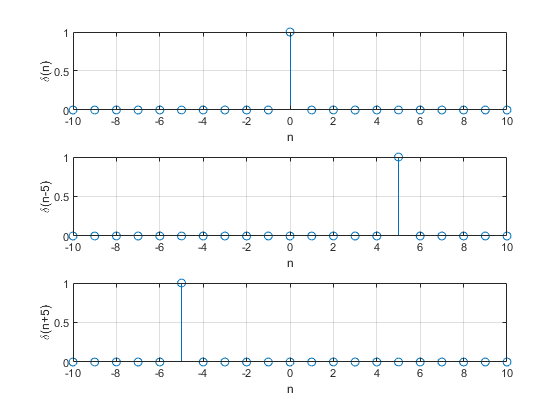

clc; clear all; close all;

n=-10:10; x=[n==0];

figure;

subplot(3,1,1);
stem (n,x); xlabel('n');ylabel('\delta(n)'); grid on

x1=[(n-5)==0];

subplot(3,1,2);
stem (n,x1);xlabel('n');ylabel('\delta(n-5)'); grid on
x2=[(n+5)==0];

subplot(3,1,3);
stem (n,x2);xlabel('n');ylabel('\delta(n+5)'); grid on

## `Question-02`

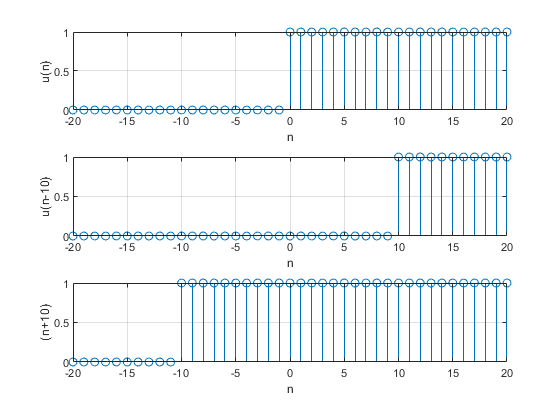

clc; clear all; close all;

n=-20:20;

x=[n>=0];

figure;
subplot(3,1,1);
stem (n,x);xlabel('n');ylabel('u(n)'); grid on

x1=[(n-10)>=0];

subplot(3,1,2);
stem (n,x1); xlabel('n');ylabel('u(n-10)'); grid on

x2=[(n+10)>=0];

subplot(3,1,3);
stem (n,x2);xlabel('n');ylabel('(n+10)'); grid on

## `Question-03`

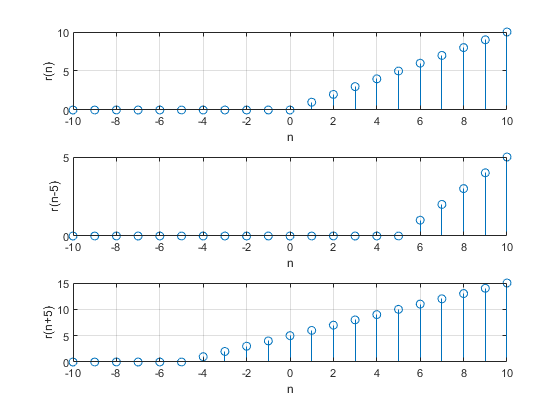

clc; clear all; close all;

n=-10:10;

x=n.*[n>=0];

figure;
subplot(3,1,1);
stem (n,x);xlabel('n');ylabel('r(n)'); grid on

x1=(n-5).*[(n-5)>=0];

subplot(3,1,2);
stem (n,x1);xlabel('n');ylabel('r(n-5)'); grid on

x2=(n+5).*[(n+5)>=0];

subplot(3,1,3);
stem (n,x2);xlabel('n');ylabel('r(n+5)'); grid on

## `Question-04`

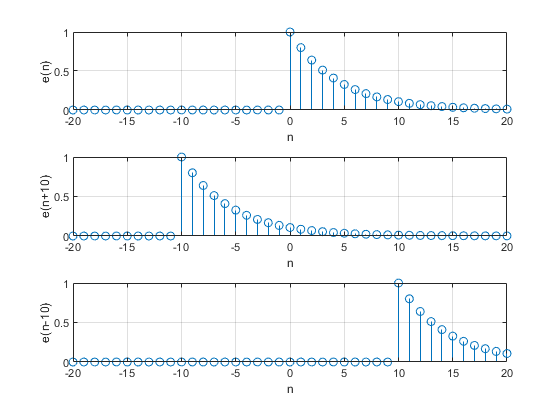

clc; clear all; close all;

n=-20:20;a=0.8;

x=(a.^n).*[n>=0];

figure;
subplot(3,1,1)
stem (n,x);xlabel('n');ylabel('e(n)'); grid on;

x1=(a.^(n+10)).*[(n+10)>=0];

subplot(3,1,2)
stem (n,x1);xlabel('n');ylabel('e(n+10)');grid on

x2=(a.^(n-10)).*[(n-10)>=0];

subplot(3,1,3)
stem (n,x2);xlabel('n');ylabel('e(n-10)'); grid on

## `Scaling Function Code:`

## **function [y,n]=ampscal(x,n,c)**

## **y=c.*x;**

## `Question-05`

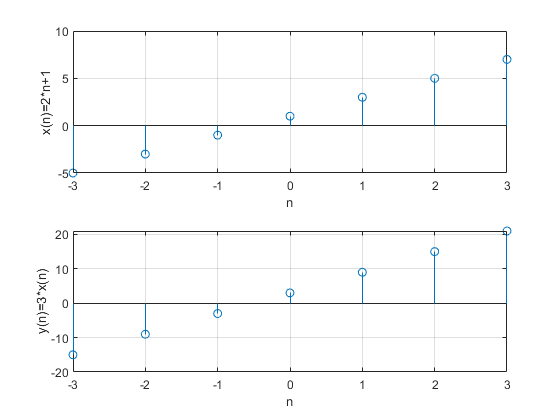

clc; clear all; close all;

n=-3:3;

x=2*n+1;
c=3;
[yc,nc]=ampscal(x,n,c);

figure;
subplot(2,1,1)
stem(n,x);xlabel('n');ylabel('x(n)=2*n+1'); grid on

subplot(2,1,2)
stem(nc,yc);xlabel('n');ylabel('y(n)=3*x(n)'); grid on

## `Shifting Function Code:`

## `function [y,n]=sigshift(x,m,n0)`

## `n=m+n0;`

## `y=x;`

## `Question-06`

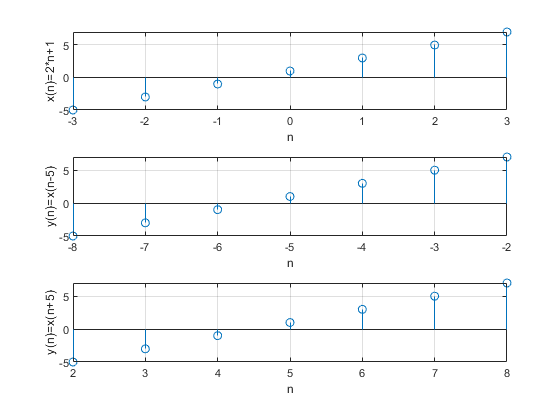

clc; close all; clear all;

n=-3:3;

x=2*n+1;
c1=-5;c2=5;
[x1,n1]=sigshift(x,n,c1);[x2,n2]=sigshift(x,n,c2);

figure;
subplot(3,1,1); stem(n,x);xlabel('n');ylabel('x(n)=2*n+1'); grid on

subplot(3,1,2); stem(n1,x1);xlabel('n');ylabel('y(n)=x(n-5)'); grid on

subplot(3,1,3); stem(n2,x2);xlabel('n');ylabel('y(n)=x(n+5)'); grid on

## `Fold Function Code:`

## `function [y,n]=sigfold(x,n)`

## `y=fliplr(x);`

## `n=-fliplr(n);`

## `Addition Function Code:`

## `function [y,n]=sigadd(x1,n1,x2,n2)`

## `min_n=min(min(n1),min(n2));`

## `max_n=max(max(n1),max(n2));`

## `n=min_n:max_n;`

## `y1=zeros(1,length(n));`

## `y2=y1;`

## `y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;`

## `y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;`

## `y=y1+y2;`

## `Multiplication Function Code:`

## `function [y,n]=sigmul(x1,n1,x2,n2)`

## `min_n=min(min(n1),min(n2));`

## `max_n=max(max(n1),max(n2));`

## `n=min_n:max_n;`

## `y1=zeros(1,length(n));`

## `y2=y1;`

## `y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;`

## `y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;`

## `y=y1.*y2;`

## `Exercise-01`

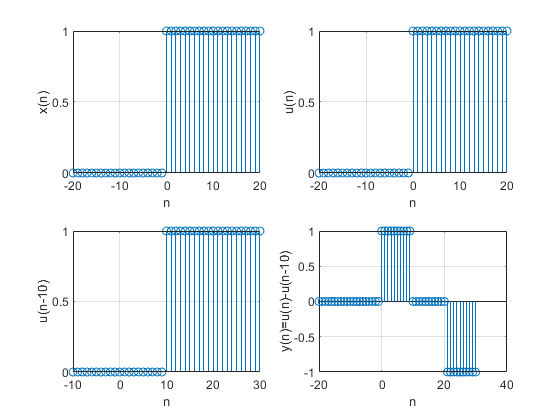

clc; clear all; close all;

n=-20:20;

x=[n>=0];
[x1,n1]=sigshift(x,n,0);
[x2,n2]=sigshift(x,n,10);
[xa,na]=sigadd(x1,n1,-x2,n2);

figure;
subplot(2,2,1)
stem(n,x);xlabel('n');ylabel('x(n)'); grid on

subplot(2,2,2)
stem(n1,x1);xlabel('n');ylabel('u(n)'); grid on

subplot(2,2,3)
stem(n2,x2);xlabel('n');ylabel('u(n-10)'); grid on

subplot(2,2,4)
stem(na,xa);xlabel('n');ylabel('y(n)=u(n)-u(n-10)'); grid on

## `Exercise-02`

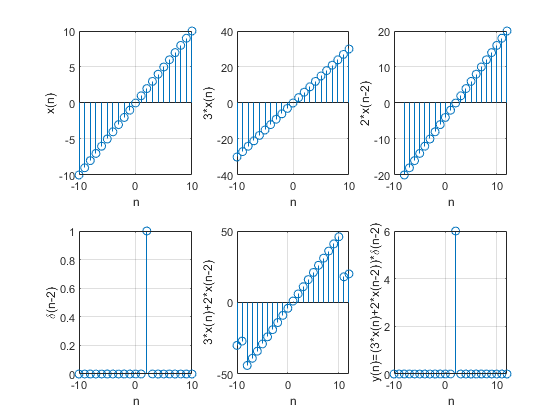

clc; clear all; close all;

n=-10:10;

x=n;
d=[(n-2)==0];
[x1,n1]=ampscal(x,n,3);
[x2,n2]=sigshift(x,n,2);
[x3,n3]=sigadd(x1,n1,2*x2,n2);
[x4,n4]=sigmul(x3,n3,d,n);

figure;
subplot(2,3,1)
stem(n,x);xlabel('n');ylabel('x(n)'); grid on

subplot(2,3,2)
stem(n1,x1);xlabel('n');ylabel('3*x(n)'); grid on

subplot(2,3,3)
stem(n2,2*x2);xlabel('n');ylabel('2*x(n-2)'); grid on

subplot(2,3,4)
stem(n,d);xlabel('n');ylabel('\delta(n-2)'); grid on

subplot(2,3,5)
stem(n3,x3);xlabel('n');ylabel('3*x(n)+2*x(n-2)'); grid on

subplot(2,3,6)
stem(n4,x4);xlabel('n');ylabel('y(n)=(3*x(n)+2*x(n-2))*\delta(n-2)'); grid on

## `Exercise-03`

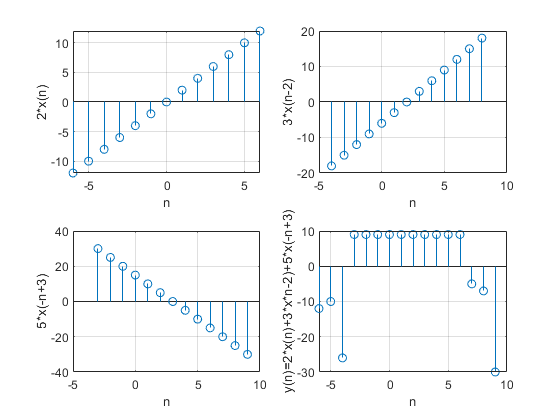

clc; clear all; close all;

n=-6:6;

x=n;
[x1,n1]=ampscal(x,n,2);
[x2,n2]=sigshift(x,n,2);
[x3a,n3a]=sigfold(x,n);
[x3,n3]=sigshift(x3a,n3a,3);
[xa,na]=sigadd(x1,n1,3*x2,n2);
[xb,nb]=sigadd(xa,na,5*x3,n3);

figure;
subplot(2,2,1)
stem(n1,x1);xlabel('n');ylabel('2*x(n)'); grid on

subplot(2,2,2)
stem(n2,3*x2);xlabel('n');ylabel('3*x(n-2)'); grid on

subplot(2,2,3)
stem(n3,5*x3);xlabel('n');ylabel('5*x(-n+3)'); grid on

subplot(2,2,4)
stem(nb,xb);xlabel('n');ylabel('y(n)=2*x(n)+3*x*n-2)+5*x(-n+3)'); grid on

## `Exercise-04`

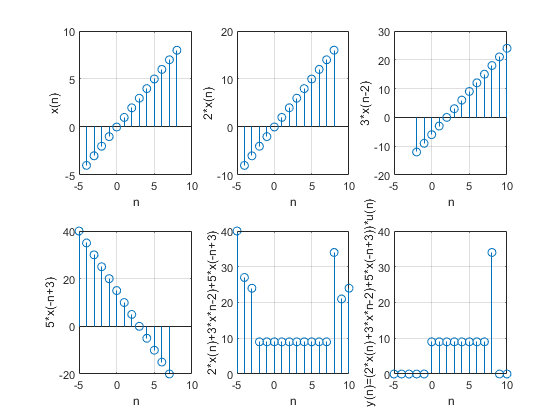

clc; clear all; close all;

n=-4:8;

x=n;
u=[n>=0];
[x1,n1]=ampscal(x,n,2); 
[x2,n2]=sigshift(x,n,2);
[x3a,n3a]=sigfold(x,n);
[x3,n3]=sigshift(x3a,n3a,3);
[xa,na]=sigadd(x1,n1,3*x2,n2);
[xb,nb]=sigadd(xa,na,5*x3,n3);
[xc,nc]=sigmul(xb,nb,u,n);

figure;
subplot(2,3,1)
stem(n,x);xlabel('n');ylabel('x(n)'); grid on

subplot(2,3,2)
stem(n1,x1);xlabel('n');ylabel('2*x(n)'); grid on

subplot(2,3,3)
stem(n2,3*x2);xlabel('n');ylabel('3*x(n-2)'); grid on

subplot(2,3,4)
stem(n3,5*x3);xlabel('n');ylabel('5*x(-n+3)'); grid on

subplot(2,3,5)
stem(nb,xb);xlabel('n');ylabel('2*x(n)+3*x*n-2)+5*x(-n+3)'); grid on

subplot(2,3,6)
stem(nc,xc);xlabel('n');ylabel('y(n)=(2*x(n)+3*x*n-2)+5*x(-n+3))*u(n)'); grid on

## `Exp-02`

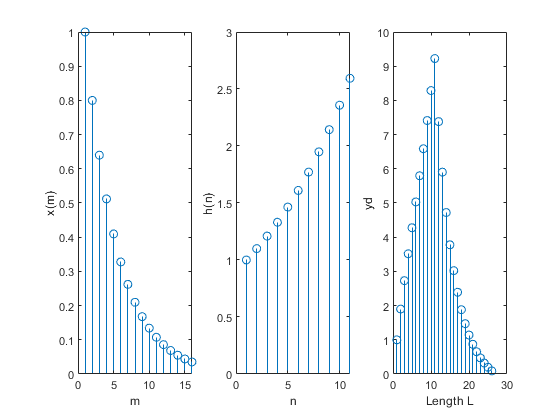

%Section-01

clc; close all ; clear all
m= 0:1:15;
n= 0:1:10;

x= (0.80).^m; 
h= (1.1).^n;

yd= conv(x,h);
Lx= length(x);
Lh= length(h);
L= Lx+Lh-1;

figure;
subplot(1,3,1)
stem(x)
xlabel('m')
ylabel('x(m)')

subplot(1,3,2)
stem(h)
xlabel('n')
ylabel('h(n)')

subplot(1,3,3)
stem(yd)
xlabel('Length L')
ylabel('yd')

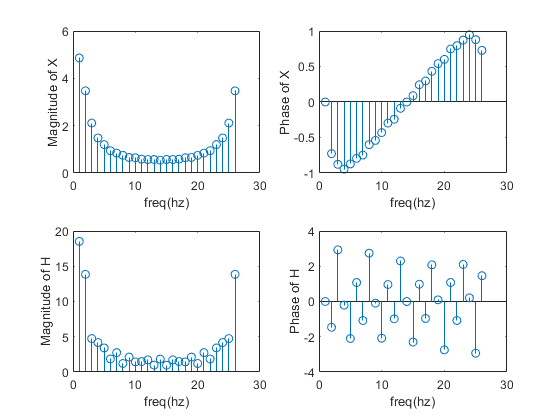



%Section-02

X= fft(x,L);
H= fft(h,L);
mX= abs(X);
pX= angle(X);
mH= abs(H);
pH= angle(H);

figure;
subplot(2,2,1)
stem(mX)
xlabel('freq(hz)')
ylabel('Magnitude of X')

subplot(2,2,2)
stem(pX)
xlabel('freq(hz)')
ylabel('Phase of X')

subplot(2,2,3)
stem(mH)
xlabel('freq(hz)')
ylabel('Magnitude of H')

subplot(2,2,4)
stem(pH)
xlabel('freq(hz)')
ylabel('Phase of H')

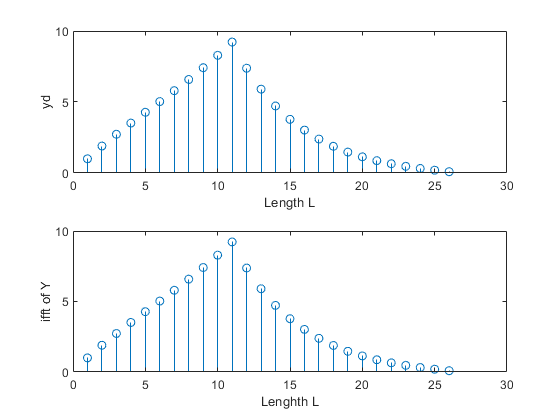



%Section-03

Y= X.*H;
yf=ifft(Y,L);

figure;
subplot(2,1,1)
stem(yd)
xlabel('Length L')
ylabel('yd')

subplot(2,1,2)
stem(yf)
xlabel('Lenghth L')
ylabel('ifft of Y')

## `Exp-03`

## `Section-01`

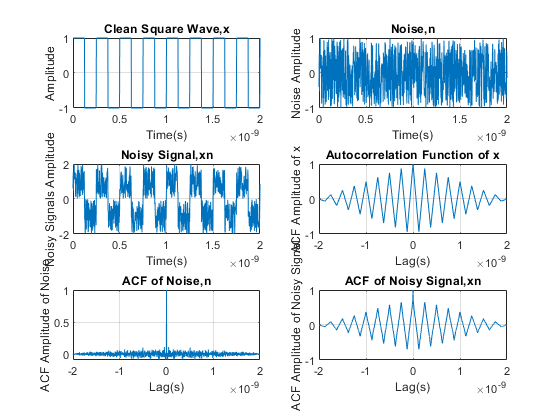

clc; close all;; clear all;

duty=50;
f=4*10.^9;
ti=1/f;
s=ti/100;
t=0:s:8*ti;
x=square(2*pi*f*t,duty);

a=1;b=-1;
N= (b-a).*rand(size(t,2),1)+a;
n=transpose(N);
xn= x+n;

[ACFx,lagx]= xcorr(x,'coeff');
[ACFn,lagn]= xcorr(n,'coeff');
[ACFxn,lagxn]= xcorr(xn,'coeff');

figure;
subplot(3,2,1)
plot(t,x)
title('Clean Square Wave,x')
xlabel('Time(s)')
ylabel('Amplitude')
grid on

subplot(3,2,2)
plot(t,n)
title('Noise,n')
xlabel('Time(s)')
ylabel('Noise Amplitude')
grid on

subplot(3,2,3)
plot(t,xn)
title('Noisy Signal,xn')
xlabel('Time(s)')
ylabel('Noisy Signals Amplitude')
grid on

subplot(3,2,4)
plot(lagx*s,ACFx)
title('Autocorrelation Function of x')
xlabel('Lag(s)')
ylabel('ACF Amplitude of x')
grid on

subplot(3,2,5)
plot(lagn*s,ACFn)
title('ACF of Noise,n')
xlabel('Lag(s)')
ylabel('ACF Amplitude of Noise')
grid on

subplot(3,2,6)
plot(lagxn*s,ACFxn)
title('ACF of Noisy Signal,xn')
xlabel('Lag(s)')
ylabel('ACF Amplitude of Noisy Signal')
grid on

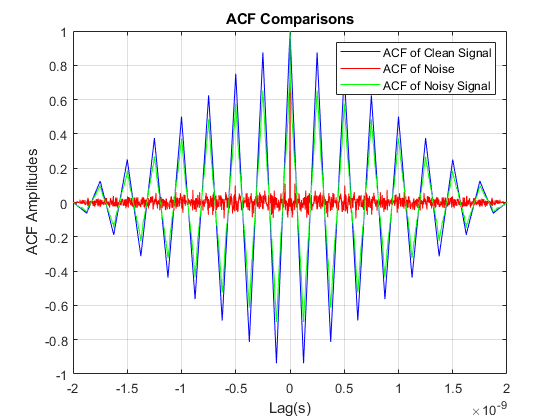


figure;
plot(lagx*s,ACFx,'-b',lagn*s,ACFn,'-r',lagxn*s,ACFxn,'-g')
title('ACF Comparisons')
xlabel('Lag(s)')
ylabel('ACF Amplitudes')
legend('ACF of Clean Signal','ACF of Noise','ACF of Noisy Signal')
grid on

## `Section-02`

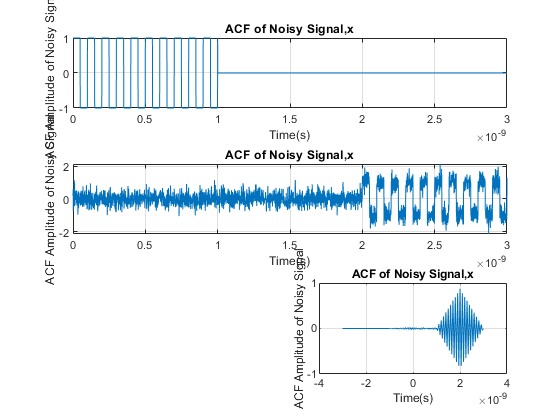

clc; close all;; clear all;

duty = 50;
f = 10*10.^9;
ti=1/f;

s = ti/100;
t1 = 0:s:10*ti;
x1 = square(2*pi*f*t1,duty);
n1=t1/s;

tdelay=20*ti;
n0=tdelay/(s);
[x2,n2]=sigshift(x1,n1,n0);
t2=n2*s;

min_n=min(min(n1),min(n2));
max_n=max(max(n1),max(n2));
n=min_n:max_n;
t=n*s;

y1=zeros(1,length(n));
y2=y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;

y2n=awgn(y2,5,'measured');

[CCF,lagx] = xcorr(y2n,y1,'coeff'); 

figure;
subplot(3,1,1)
plot(t,y1)
title('ACF of Noisy Signal,x')
xlabel('Time(s)')
ylabel('ACF Amplitude of Noisy Signal')
grid on

subplot(3,1,2)
plot(t,y2n)
title('ACF of Noisy Signal,x')
xlabel('Time(s)')
ylabel('ACF Amplitude of Noisy Signal')
grid on

subplot(3,2,6)
plot(lagx*s,CCF)
title('ACF of Noisy Signal,x')
xlabel('Time(s)')
ylabel('ACF Amplitude of Noisy Signal')
grid on

## `Exp-04`

## `Exercise-01/02`

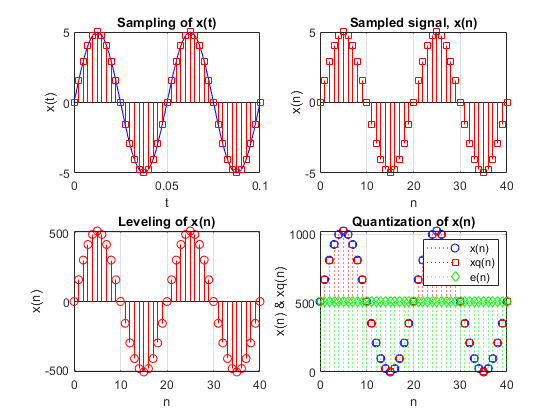

% Analog to Digital Conversion

clc; close all; clear;

% General Instructions:
% Depending on question, may have to vary signal parameters like Amplitude
% & Frequency of signal, it's Smapling Period/Frequency, Total runtime period
% (eg. 2*T ( For 2 cycles), 5*T (For 5 cycles)), type of signal (Sine or Cosine),
% bitrate (bits/sample) of signal etc.

% Exercise wise Instructions:
% For Exercise-01, you will be asked to vary sampling frequency (50, 100, 200)
% for a fixed bitrate (10 this time) and for Exercise-02, you will be asked
% to vary bitrate (3, 4, 5, 10) for a fixed sampling frequency (400 this time).
% Or instead of mentioning bitrate, quantization level may be mentioned and
% asked to vary (8, 16, 32, 1024) as QL = 2^b-1 (~2^b).

% Analog signal
b=10; % number of bits/sample;
A=5; % Amplitude of analog signal
f = 20; %% Frequency of the analog signal
T = 1/f; %% Period of the analog signal
tmin = 0; tmax = 2*T; %% The signal is for 2 period
dt = T/50; %%
t = tmin:dt:tmax;
xt = A*sin(2*pi*f*t);

% Sampling
Fs = 400;
dts = 1/Fs;
ts = tmin:dts:tmax;
xs = A*sin(2*pi*f*ts);
n=0:1:(length(ts)-1);

%Quantixation of xs
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error

% Coding for digital signal
xd=dec2bin(xq,b);

% Reconstruction of xt (basic)
xtr=(bin2dec(xd)-L/2)*del;

figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t)')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on

subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n)')
ylim([-A A])
grid on

subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n)')
ylim([-L/2 L/2])
grid on

subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n)')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

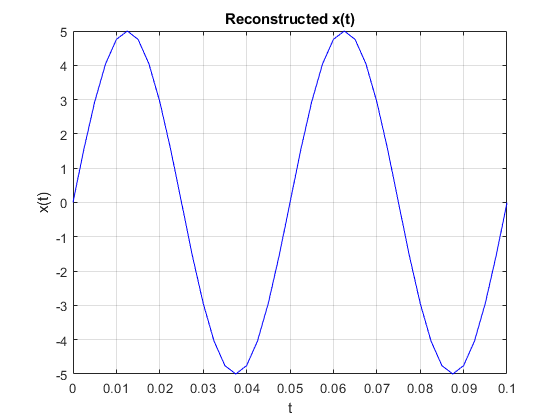


figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t)')
grid on

## `Exercise-03`

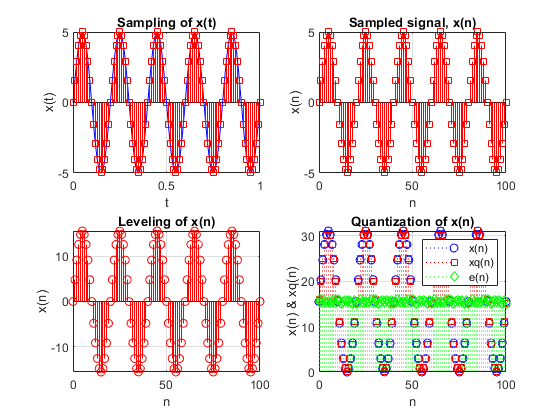

% Analog to Digital Conversion

clc; close all; clear all;

% General Instruction:
% First, you will standardly process a signal & then at the end, find SQNR
% by varying bitrate 'b' from 0 to 16.

% Analog signal
b = 5; % number of bits/sample;
A=5; % Amplitude of analog signal
f =5; %% Frequency of the analog signal
T = 1/f; %% Period of the analog signal
tmin = 0; tmax = 5*T; %% The signal is for 2 period
dt = T/100; %%
t = tmin:dt:tmax;
xt = A*sin(2*pi*f*t);

% Sampling
Fs = 100;
dts = 1/Fs;
ts = tmin:dts:tmax;
xs = A*sin(2*pi*f*ts);
n=0:1:(length(ts)-1);

%Quantixation of xs
del=2*A/(2^b-1); % quantization step
xL=(xs/del); %% Laveling according to quantization level
L=2^b-1; %% No. of quantization level
xq=round(xL-min(xL)); %% Leveling & quantization
e=xq-xL; % Quantization error

% Coding for digital signal
xd=dec2bin(xq,b);

% Reconstruction of xt (basic)
xtr=(bin2dec(xd)-L/2)*del;

figure;
subplot(2,2,1)
plot(t,xt,'-b');
hold on
stem(ts,xs,'rs');
title('Sampling of x(t)')
xlabel('t')
ylabel('x(t)')
ylim([-A A])
grid on

subplot(2,2,2)
stem(n,xs,'rs')
xlabel('n')
ylabel('x(n)')
title('Sampled signal, x(n)')
ylim([-A A])
grid on

subplot(2,2,3)
stem(n,xL,'r')
xlabel('n')
ylabel('x(n)')
title('Leveling of x(n)')
ylim([-L/2 L/2])
grid on

subplot(2,2,4)
stem(n,xL+L/2,':bo')
hold on
stem(n,xq,':rs')
hold on
stem(n,e,':gd')
xlabel('n')
ylabel('x(n) & xq(n)')
title('Quantization of x(n)')
legend('x(n)','xq(n)','e(n)')
ylim([0 L])
grid on

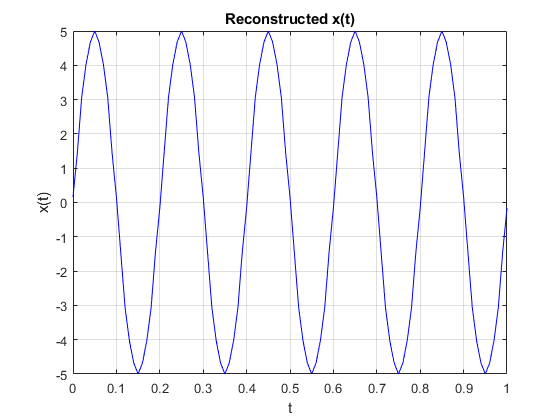


figure;
plot(ts,xtr,'-b')
xlabel('t')
ylabel('x(t)')
title('Reconstructed x(t)')
grid on


%SQNR vs b

for b = 1:16;
sqnr(b) = 1.76 + 6.02*b;
end
sqnr

sqnr =     7.7800   13.8000   19.8200   25.8400   31.8600   37.8800   43.9000   49.9200   55.9400   61.9600   67.9800   74.0000   80.0200   86.0400   92.0600   98.0800


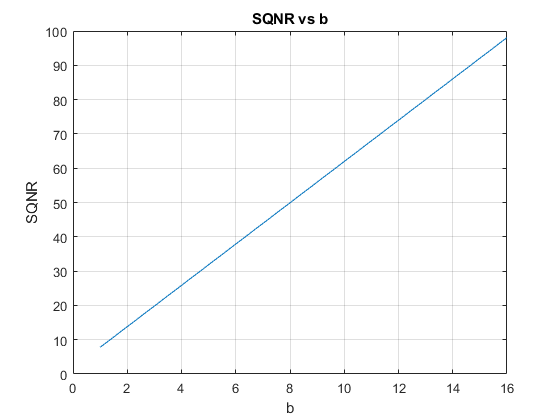

plot(sqnr)
xlabel('b')
ylabel('SQNR')
title('SQNR vs b')
grid on

## `Exp-05`

clc; close all; clear all;

%coefficients

a = [1 2 1];
b = [1 -1.2 0.75];
Fs = 5*10^3;
T = 1/Fs;

%transfer function

H = tf(a,b,T,'variable','z^-1')

H =
 
     1 + 2 z^-1 + z^-2
  ------------------------
  1 - 1.2 z^-1 + 0.75 z^-2
 
Sample time: 0.0002 seconds
Discrete-time transfer function.



[zero,pole] =  tf2zp(a,b)

zero =     -1
    -1


pole =    0.6000 + 0.6245i
   0.6000 - 0.6245i


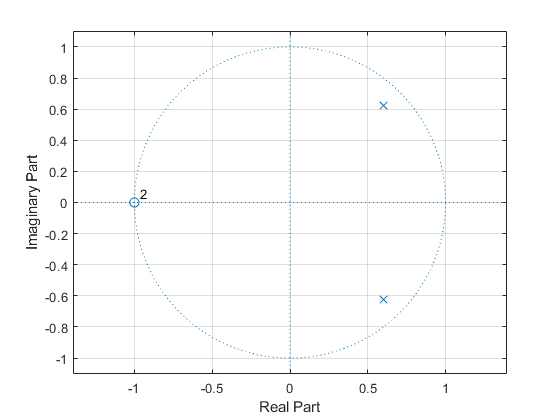


%zeros & poles plot

figure;
zplane(a,b);
grid on


%freqency domain analysis

N = 512;
Hz = freqz(a,b,N,'whole');
Mz = abs(Hz);
Mzmax = max(Mz)

Mzmax = 18.8947

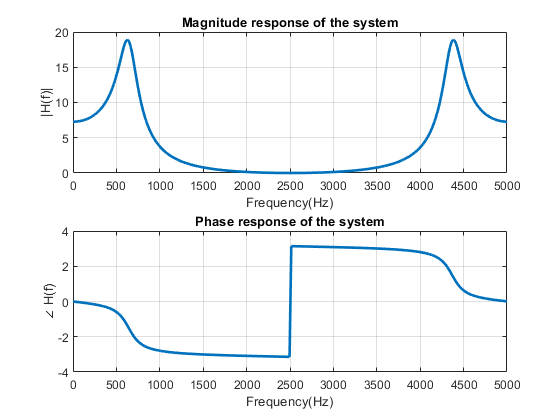

Pz = angle(Hz);
f = 0:Fs/(N-1):Fs;

%Plot in the frequency domain

figure;
subplot(2,1,1)
plot(f,Mz,'linewidth',2)
title('Magnitude response of the system')
xlabel('Frequency(Hz)')
ylabel('|H(f)|')
grid on

subplot(2,1,2)
plot(f,Pz,'linewidth',2)
title('Phase response of the system')
xlabel('Frequency(Hz)')
ylabel('\angle H(f)')
grid on

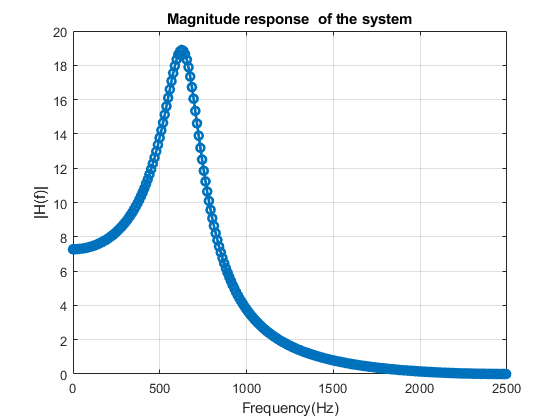


%finding max-magnitude frequency & bandwidth

figure
plot(f,Mz,'-o','linewidth',2,'MarkerIndices',1:length(Mz))
xlim([0 Fs/2])
title('Magnitude response  of the system');
xlabel('Frequency(Hz)');
ylabel('|H(f)|')
grid on

## `Exp-06`

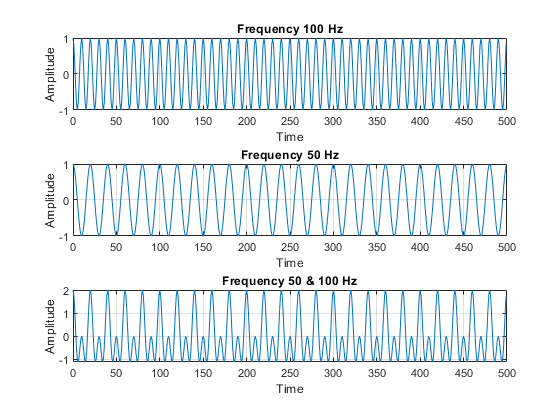

clc; close all, clear all;

% Sampling informations
Fs=1000; 
T=1/Fs;

% Input frquency informations
F1=100; 
F2=50;
n=0:1:Fs/2-1;

% Signals in time-domain
s1=cos(2*pi*F1*n*T);
s2=cos(2*pi*F2*n*T);
s=s1+s2;

% System's impulse response
h=[1 -1.9021130326 1];

N=Fs/2;
df=1/(N*T);
f=n*df;

% Transforming signals to frequency domain
FFT100=abs(fft(s1,N)); % Fourier transform of s1
FFT50=abs(fft(s2,N)); % Fourier transform of s2
FFT150=abs(fft(s,N)); % Fourier transform of s
FFTh=abs(fft(h,N)); % Fourier transform of h
FFTy=FFT150.*FFTh; % Multiplication
y=ifft(FFTy,N); % Inverse Fourier transform to get time-domain sequence

figure;
subplot(3,1,1) % Time-domain s1
plot(n,s1)
title('Frequency 100 Hz')
xlabel('Time')
ylabel('Amplitude')
grid on
subplot(3,1,2); % Time-domain s2
plot(n,s2)
title('Frequency 50 Hz')
xlabel('Time')
ylabel('Amplitude')
grid on
subplot(3,1,3); % Time-domain s
plot(n,s)
title('Frequency 50 & 100 Hz')
xlabel('Time')
ylabel('Amplitude')
grid on

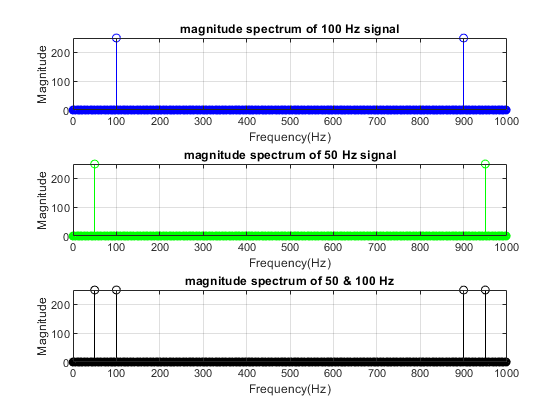


figure;
subplot(3,1,1); % Frequency-domain s1
stem(f,FFT100,'-b')
title('magnitude spectrum of 100 Hz signal')
xlabel('Frequency(Hz)')
ylabel('Magnitude')
grid on
subplot(3,1,2); % Frequency-domain s2
stem(f,FFT50,'-g')
title('magnitude spectrum of 50 Hz signal')
xlabel('Frequency(Hz)')
ylabel('Magnitude')
grid on
subplot(3,1,3); % Frequency-domain s
stem(f,FFT150,'-k')
title('magnitude spectrum of 50 & 100 Hz')
xlabel('Frequency(Hz)')
ylabel('Magnitude')
grid on

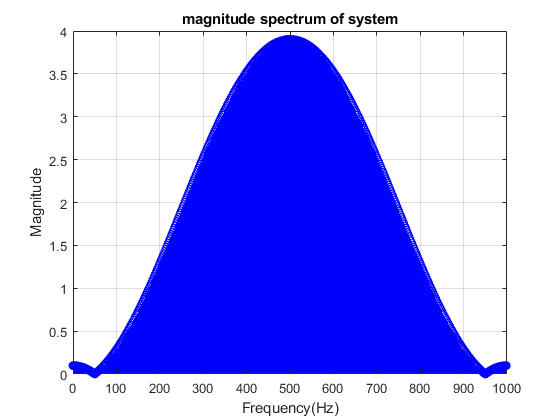


figure; % Frequency-domain h
stem(f,FFTh,'-b')
title('magnitude spectrum of system')
xlabel('Frequency(Hz)')
ylabel('Magnitude')
grid on

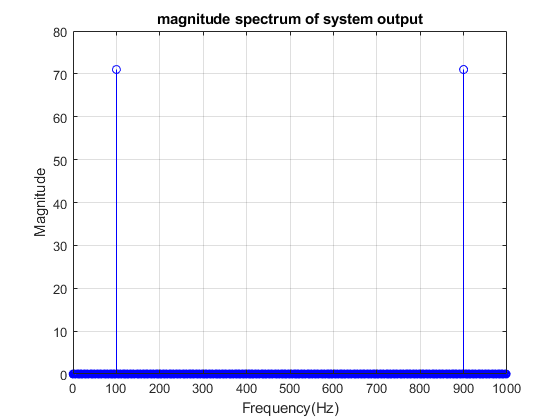


figure;
stem(f,FFTy,'-b'); % Frequency-domain y
title('magnitude spectrum of system output')
xlabel('Frequency(Hz)')
ylabel('Magnitude')
grid on

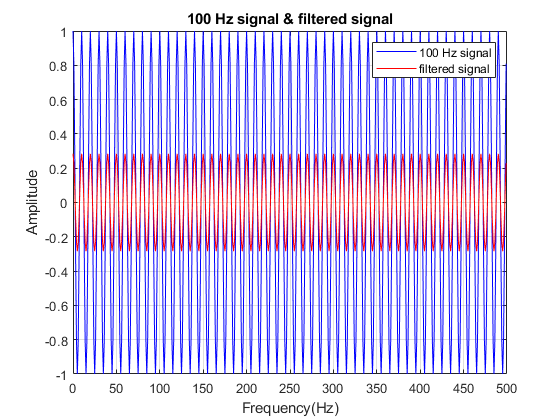


figure; % Time-domain s1 & time-domain y
plot(n,s1,'-b',n,y,'-r')
title('100 Hz signal & filtered signal')
xlabel('Frequency(Hz)')
ylabel('Amplitude')
legend('100 Hz signal','filtered signal')
grid on

## `Exp-07`

## `Section-01: Low-Pass Filter Design`

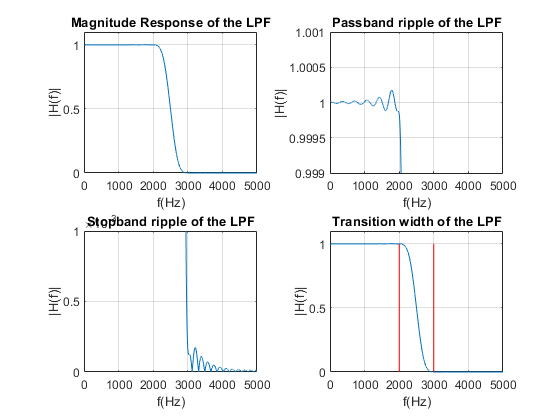

% LowPass

clc; close all; clear all;

M=28; 
N=2*M+1; % Filter Length
tw=1000; % Transition Width
Fs=10000; % Sampling Frequency
f=2000+tw/2; % fp(ideal)
Ts=1/Fs;
n=-M:M;

%w=window(@hamming,N); % Hamming Window
w=window(@blackman,N); % Blackman Window
%w=window(@rectwin,N); % Rectangular Window

wp=2*pi*f; % Passband Edge Frequency in rads^-1

h=zeros(1,N); 
h=sin(wp.*n.*Ts)./(n*pi);
h(round(length(h)/2))=wp*Ts/pi;

hn=w'.*h; % Impulse Response

N=20480;
Y=abs(fft(hn,N));

f=0:Fs/(N-1):Fs;

figure;

subplot(2,2,1)
plot(f,Y);title('Magnitude Response of the LPF')
axis([0 Fs/2,0 1.1]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,2)
plot(f,Y);title('Passband ripple of the LPF')
axis([0 Fs/2,0.999 1.001]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,3)
plot(f,Y);title('Stopband ripple of the LPF')
axis([0 Fs/2, 0 0.001]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,4)
plot(f,Y); title('Transition width of the LPF')
hold on;
plot([2500-tw/2, 2500-tw/2], [0, 1], '-r');
plot([2500+tw/2, 2500+tw/2], [0, 1], '-r');
axis([0 Fs/2,0 1.1]);xlabel('f(Hz)'); ylabel('|H(f)|');
grid on;
hold off;

## `Section-02: High-Pass Filter Design`

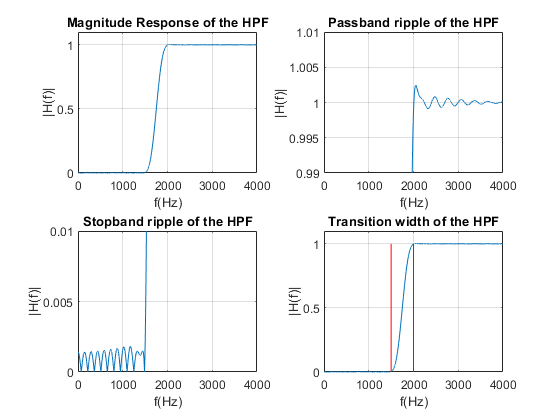

% HighPass

clc; close all; clear all;

M=27;
N=2*M+1;
tw=500;
Fs=8000;
f=2000-tw/2; % fp(ideal)
Ts=1/Fs;
n=-M:M;

w=window(@hamming,N); % Hamming Window
%w=window(@blackman,N); %Blackman Window
%w=window(@rectwin,N); % Rectangular Window

wp=2*pi*f;

h=zeros(1,N); 
h=0-sin(wp.*n.*Ts)./(n*pi);
h(round(length(h)/2))=1-wp*Ts/pi;

hn=w'.*h; %Impulse response

N=20480;
Y=abs(fft(hn,N));

f=0:Fs/(N-1):Fs;

figure;

subplot(2,2,1)
plot(f,Y);title('Magnitude Response of the HPF')
axis([0 Fs/2,0 1.1]);xlabel('f(Hz)');ylabel('|H(f)|');grid on

subplot(2,2,2)
plot(f,Y);title('Passband ripple of the HPF')
axis([0 Fs/2,0.99 1.01]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,3)
plot(f,Y);title('Stopband ripple of the HPF')
axis([0 Fs/2, 0 0.01]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,4)
plot(f,Y); title('Transition width of the HPF')
hold on;
plot([1750-tw/2, 1750-tw/2], [0, 1], '-r');
plot([1750+tw/2, 1750+tw/2], [0, 1], '-r');
axis([0 Fs/2,0 1.1]);xlabel('f(Hz)'); ylabel('|H(f)|');
grid on;
hold off;

## `Section-03: Band-Pass Filter Design`

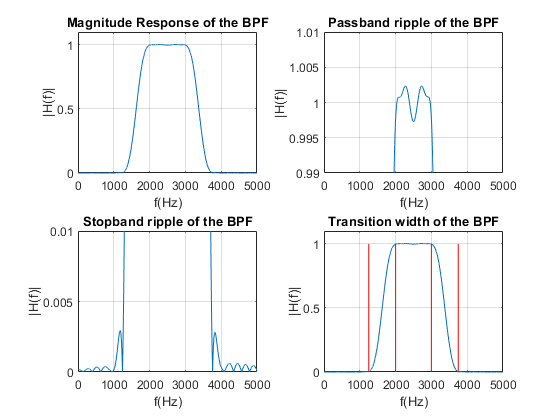

% BandPass

clc; close all; clear all;

M=36;
N=2*M+1;
tw=750;
Fs=16000;
f1=3000+tw/2;
f2=2000-tw/2;
Ts=1/Fs;
n=-36:36;

w=window(@hamming,N);

w1=2*pi*f1; 
w2=2*pi*f2;

h1=zeros(1,N); 
h1=sin(w1.*n.*Ts)./(n*pi);
h1(round(length(h1)/2))=w1*Ts/pi;

h2=zeros(1,N); 
h2=sin(w2.*n.*Ts)./(n*pi);
h2(round(length(h2)/2))=w2*Ts/pi;

h=h1-h2;

h=w'.*h;

N=20480;
Y=abs(fft(h,N));

f=0:Fs/(N-1):Fs;

figure;

subplot(2,2,1)
plot(f,Y);title('Magnitude Response of the BPF')
axis([0 5000,0 1.1]);xlabel('f(Hz)');ylabel('|H(f)|');grid on

subplot(2,2,2)
plot(f,Y);title('Passband ripple of the BPF')
axis([0 5000,0.99 1.01]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,3)
plot(f,Y);title('Stopband ripple of the BPF')
axis([0 5000, 0 0.01]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,4)
plot(f,Y); title('Transition width of the BPF')
hold on;
plot([2000-750, 2000-750], [0, 1], '-r');
plot([2000, 2000], [0, 1], '-r');
plot([3000+750, 3000+750], [0, 1], '-r');
plot([3000, 3000], [0, 1], '-r');
axis([0 5000,0 1.1]);xlabel('f(Hz)'); ylabel('|H(f)|');
grid on;
hold off;

## `Section-04: Band-Stop Filter Design`

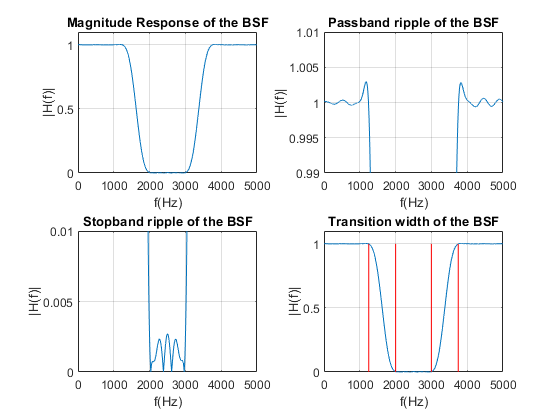

% BandStop

clc; close all; clear all;

M=36;
N=2*M+1;
tw=750;
Fs=16000;
Ts=1/Fs;
fp1=3000+tw/2;
fp2=2000-tw/2;
n=-M:M;

w=window(@hamming,N);

wp1=2*pi*fp1;
wp2=2*pi*fp2;

h1=zeros(1,N);
h1=sin(wp1.*n.*Ts)./(n*pi);
h1(round(length(h1)/2))=wp1*Ts/pi;

h2=zeros(1,N);
h2=sin(wp2.*n.*Ts)./(n*pi);
h2(round(length(h2)/2))=wp2*Ts/pi;

h=0-(h1-h2);
h(round(length(h)/2))=1-(wp1*Ts/pi-wp2*Ts/pi);
h=w'.*h;

N=20480;
Y=abs(fft(h,N));

f=0:Fs/(N-1):Fs;

figure;

subplot(2,2,1)
plot(f,Y);title('Magnitude Response of the BSF')
axis([0 5000,0 1.1]);xlabel('f(Hz)');ylabel('|H(f)|');grid on

subplot(2,2,2)
plot(f,Y);title('Passband ripple of the BSF')
axis([0 5000,0.99 1.01]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,3)
plot(f,Y);title('Stopband ripple of the BSF')
axis([0 5000, 0 0.01]);xlabel('f(Hz)');ylabel('|H(f)|');
grid on;

subplot(2,2,4)
plot(f,Y); title('Transition width of the BSF')
hold on;
plot([2000-750, 2000-750], [0, 1], '-r');
plot([2000, 2000], [0, 1], '-r');
plot([3000+750, 3000+750], [0, 1], '-r');
plot([3000, 3000], [0, 1], '-r');
axis([0 5000,0 1.1]);xlabel('f(Hz)'); ylabel('|H(f)|');
grid on;
hold off;

## `Exp-08`

## `Section-01`

clc; close all; clear all;
% Q.2.1: Transfer function, Pole-zero and BW
%y[n]=1.25y[n-1]-0.78125y[n-2]+x[n]+2x[n-1]+x[n-2]
 
b= [1 2 1];a = [1 -1.25 0.78125];       % coefficients 
H= tf(b,a,1/10^4,'variable','z^-1')   % Transfer function 

H =
 
       1 + 2 z^-1 + z^-2
  ---------------------------
  1 - 1.25 z^-1 + 0.7812 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



[zero,pole] = tf2zp(b,a)                % Obtain zero-pole-gain

zero =     -1
    -1


pole =    0.6250 + 0.6250i
   0.6250 - 0.6250i


a=abs(pole)';
r=a(:,1);            % Distance of pole from the origin
BWn=2*(abs(1-r)./sqrt(r));           %normalized BW of the filter
Fs=10000;
BWf=(Fs/(2*pi))*BWn

BWf = 393.1395

## `Section-02`

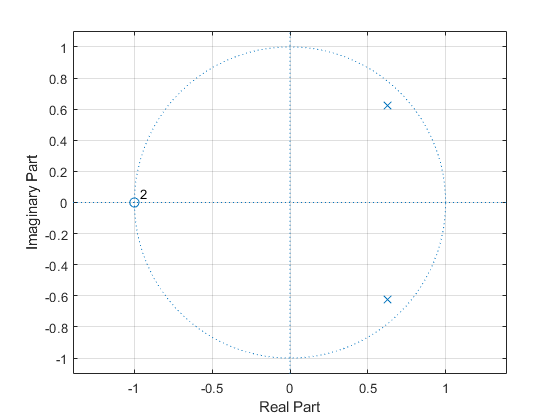

clc; close all; clear all;
%Q.2.2: zplane to show the pole-zero plot
%y[n]=1.25y[n-1]-0.78125y[n-2]+x[n]+2x[n-1]+x[n-2]
b = [1 2 1];                         % num coefficientas               
a = [1 -1.25 0.78125];               % den coefficientas 
zplane(b,a);
grid on

## `Section-03`

clc; close all; clear all;
b=[1 2 1]; 
a=[1 -1.25 0.78125];  
z=abs(freqz(b,a,512,'whole'));
RMS=0.707*max(z)

RMS = 15.6736

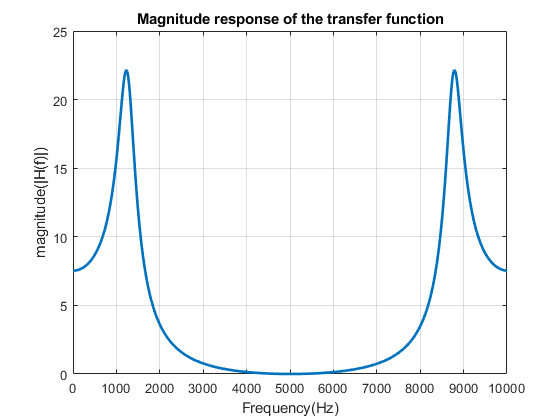

k=0:10000/511:10000;

figure;
plot(k,z,'linewidth',2)
title('Magnitude response of the transfer function');
xlabel('Frequency(Hz)');ylabel('magnitude(|H(f)|)')
grid on

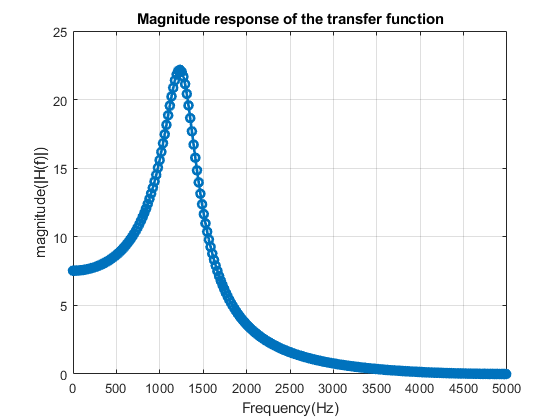

figure;
plot(k,z,'-o','linewidth',2,'MarkerIndices',1:length(z))
xlim([0 5000])
title('Magnitude response of the transfer function');
xlabel('Frequency(Hz)');ylabel('magnitude(|H(f)|)')
grid on

## `Following, we included the function codes inside the live script, so that we don't have to keep the function files (eg. sigadd, sigshift etc.) in the same folder with this file to make functions work. functions have to be put at the last of the live script editor because you can't create any more sections after it, so if you have to create any more section after Exp-08 Section-03, create it before this text section. Don't modify the following functions' section if you want to run this file as it is. But if you want to do it as previously we did in Lab, remove the following functions' section from this code, create separate corresponding function code files (with same file name as the function's name)  as previous, and must keep them in the same folder with this file.`

## `If the functions are coded inside the live script editor, each of them has to be started with 'function' & terminated with 'end'.`

function [y,n]=ampscal(x,n,c)
y=c.*x;
end
%Previous was the Scaling Function

%Following is the Shift Function
function [y,n]=sigshift(x,m,n0)
n=m+n0;
y=x;
end

%Fold Function
function [y,n]=sigfold(x,n)
y=fliplr(x);
n=-fliplr(n);
end

%Addition Function
function [y,n]=sigadd(x1,n1,x2,n2)
min_n=min(min(n1),min(n2));
max_n=max(max(n1),max(n2));
n=min_n:max_n;
y1=zeros(1,length(n));
y2=y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;
y=y1+y2;
end

%Multiplication Function
function [y,n]=sigmul(x1,n1,x2,n2)
min_n=min(min(n1),min(n2));
max_n=max(max(n1),max(n2));
n=min_n:max_n;
y1=zeros(1,length(n));
y2=y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;
y=y1.*y2;
end